# 適応アルゴリズム比較

## 基本

fleng     = 20;     %タップ数
ssize     = 0.1;   %ステップサイズ
fsize     = 20000;    %フレームサイズ
NI        = 1;     %イテレータ

plotf = 0;

## LMSフィルタの設計

lmsfilt = dsp.LMSFilter('Length',fleng,'Method','LMS', 'StepSize',0.0001);

## NLMSフィルタの設計

nlmsfilt = dsp.LMSFilter('Length',fleng,'Method','Normalized LMS', 'StepSize',ssize);

## APフィルタの設計

po = 6;    %次元数
apfilt = dsp.AffineProjectionFilter('Length',fleng, 'StepSize',0.5 ,'ProjectionOrder', po);

## RLSフィルタの設計

FF = 0.98;  
rlsfilt = dsp.RLSFilter(11, 'ForgettingFactor', FF);

## ノイズの生成

Hp = dsp.ColoredNoise('Color','pink','SamplesPerFrame',fsize);
pinkn = Hp();
if plotf == 1
    plot(pinkn);
end
Hw = dsp.ColoredNoise('Color','white','SamplesPerFrame',fsize);
whiten = Hw();
if plotf == 1
    plot(whiten);
end

firfilt = dsp.FIRFilter('Numerator', fir1(10,[.5, .75]));

sinewave = dsp.SineWave('Frequency',0.01, ...
    'SampleRate',1,'SamplesPerFrame',fsize);

TS1 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','LMS');
TS2 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','NLMS');
TS3 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','AP');
TS4 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','RLS');

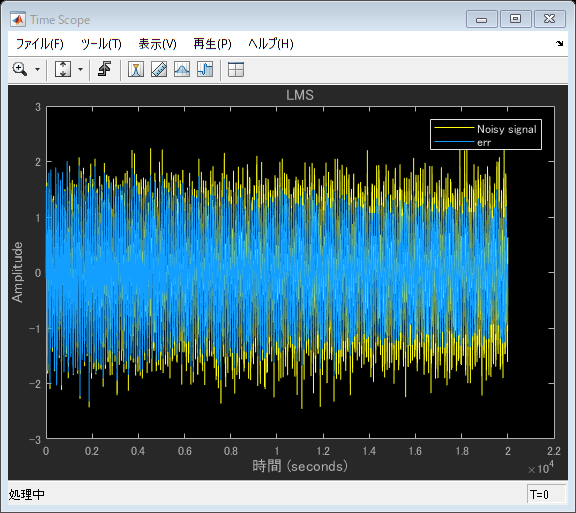

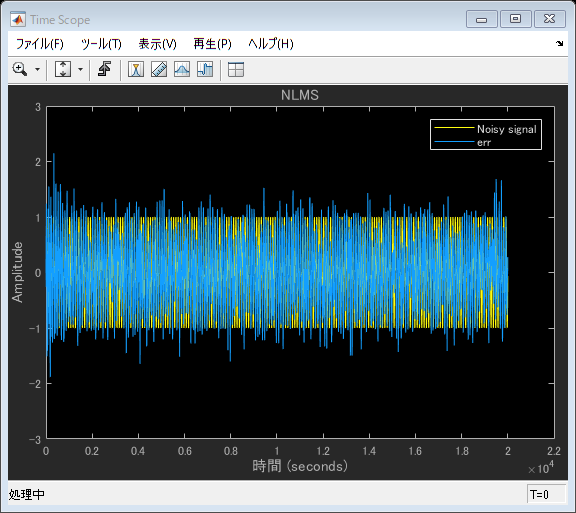

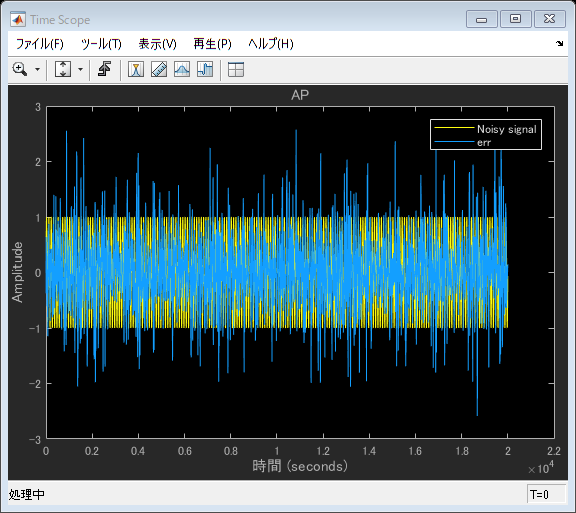

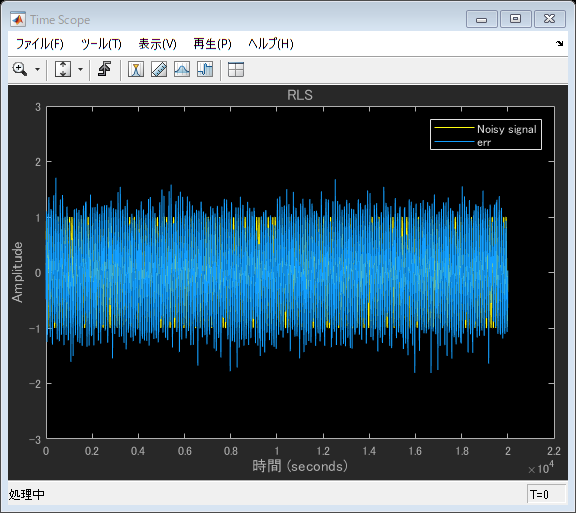

for i = 1:NI
    d = Hp();
    s = sinewave();
    x = firfilt(d)+s;
    [y1,e1] = lmsfilt(d,x);
    TS1([x,e1]);
    [y2,e2] = nlmsfilt(d,x);
    TS2([x,e2]);
    [y3,e3] = apfilt(d,x);
    TS3([x,e3]);
    [y4,e4] = rlsfilt(d,x);
    TS4([s,e4]);
end